# [Квантовая криптография](https://ru.wikipedia.org/wiki/Квантовая_криптография)

#### Ослабленные лазерные импульсы

Решение проблемы приготовления однофотонных [фоковскиих состояний](https://ru.wikipedia.org/wiki/Состояние_Фока) - ослабление лазерных импульсов, поле которых находится в когерентном состоянии со средним числом фотонов N. Вероятность найти n фотонов в таком состоянии описывается [распределением Пуассона](https://ru.wikipedia.org/wiki/Распределение_Пуассона)

clear
digits(3)
syms N n 
P(n,N)=N^n/factorial(n)*exp(-N)

$$P(n, N) = \frac{N^{n}\,{\mathrm{e}}^{-N}}{n!}$$

N1=1;
n1=0.2;
vpa(P(N1,n1))

$$ans = 0.164$$

Соответственно, вероятность того, что в непустом (n~=) импульсе содержится более одного фотона

$\begin{array}{l}
P\left(n>1|n>0,N\right)=\frac{1-P\left(0,N\right)-P\left(1,N\right)}{1-P\left(0,N\right)}=\\
=\frac{1-\left\lbrack \frac{N^0 e^{-N} }{0!}\right\rbrack -\frac{N^1 e^{-N} }{1!}}{\left\lbrack \frac{N^0 e^{-N} }{0!}\right\rbrack }=\frac{1-e^{-N} \left(1+N\right)}{1-e^{-N} }\approx \frac{N}{2}
\end{array}$                             (22)

Вероятность может быть сделана произвольно малой при уменьшении N. Однако в этом случае большинство импульсов окажется пустым! Действительно, при малых N


$$P\left(n=0\right)=\frac{N^0 }{0!}e^{-N} \to 1-N$$


Упрощенная временная развертка событий в КК представлена на рис.3

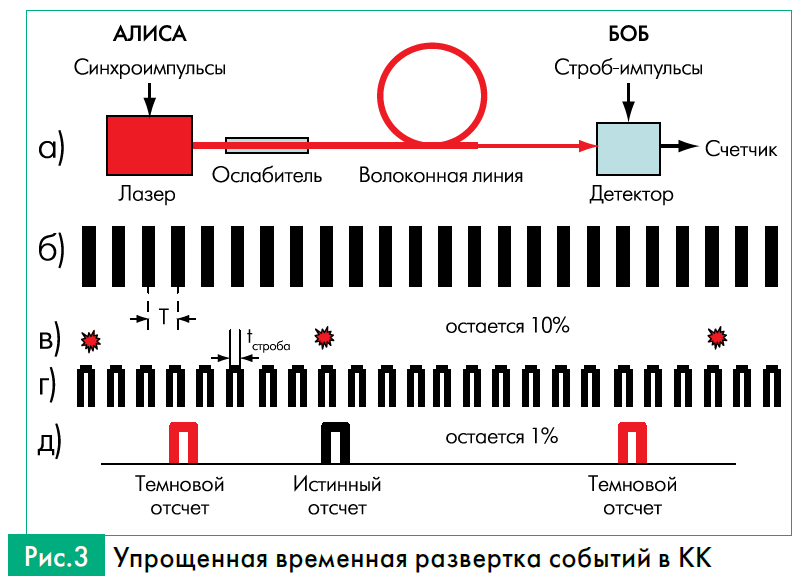

### Кодирование

#### Кодирование по поляризации

Основные состояния при кодировании по поляризации


$$\left|\updownarrow \rangle =\right|V\rangle$$



$$\left|\leftrightarrow \rangle =\right|H\rangle$$



$$\left|/\rangle \;=\frac{1}{\sqrt{2}}\left\lbrace \left|H\rangle +\right|V\rangle \right\rbrace \right.$$



$$\left|\;\backslash \rangle \;=\frac{1}{\sqrt{2}}\left\lbrace \left|H\rangle -\right|V\rangle \right\rbrace \right.$$



$$\left|L\rangle \;=\frac{1}{\sqrt{2}}\left\lbrace \left|H\rangle +i\right|V\rangle \right\rbrace \right.$$



$$\left|R\rangle \;=\frac{1}{\sqrt{2}}\left\lbrace \left|H\rangle -i\right|V\rangle \right\rbrace \right.$$


Они соответствуют вертикальной, горизонтальной, диагональным и (право- и лево) циркулярным поляризациям однофотонных фоковских состояний.

#### Кодирование по фазе

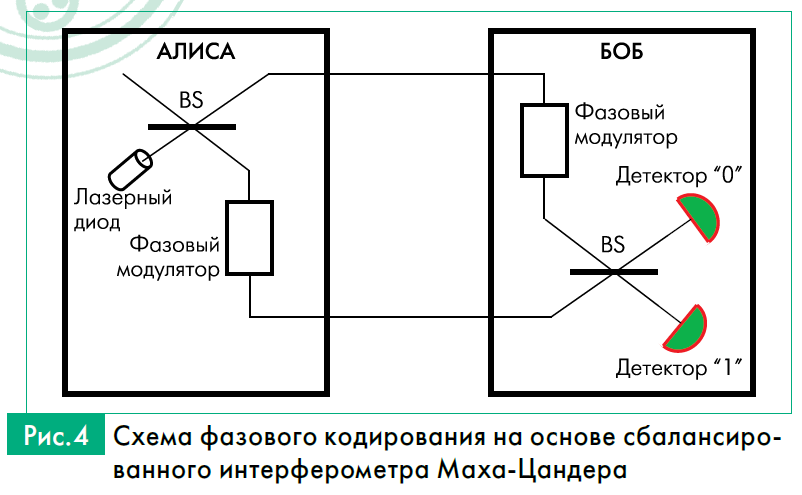

Такой споособ основан на использовании двухплечевого [интерферометра](https://ru.wikipedia.org/wiki/Интерферометр) Маха-Цандера (рис.4)

Интенсивность в выходной моде "0" станции Боба:


$$I_0 =\bar{I} \;{\mathrm{cos}}^2 \left(\frac{\phi_A -\phi_B +k\Delta L}{2}\right)$$


На практике удобнее использовать другую схему - два разбалансированных интерферометра Маха-Цандера (рис.5)

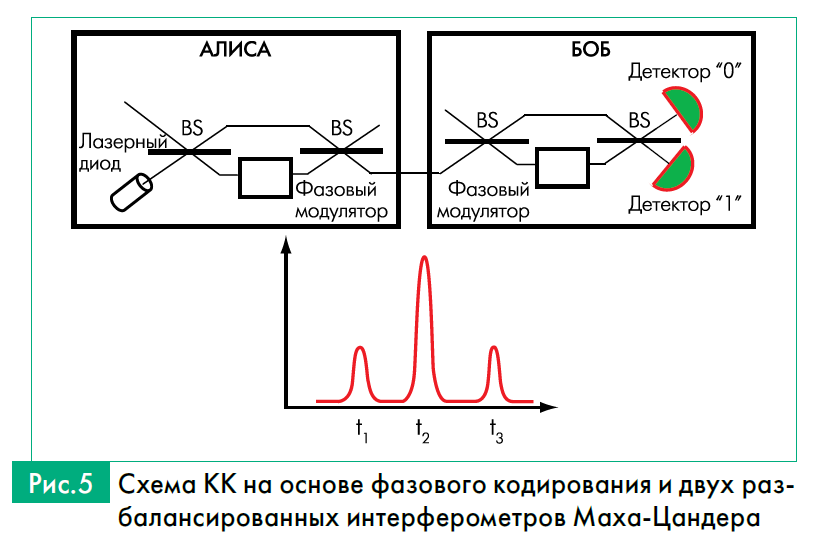

В протоколе [BB84](https://ru.wikipedia.org/wiki/BB84) используются два (или в общем случае три) взаимно несмещенных базисы, состоящих из пары ортогональных состояний. Такие базисы удовлетворяют условию


$$\left|\langle \psi_i \right|\varphi_i \rangle {\left|\right.}^2 =\frac{1}{D}$$


в то время как для состояний из одного базиса


$$\langle \psi_i \left|\psi_j \rangle =0\;\;\left(i,j=1,2\right)\right.$$
